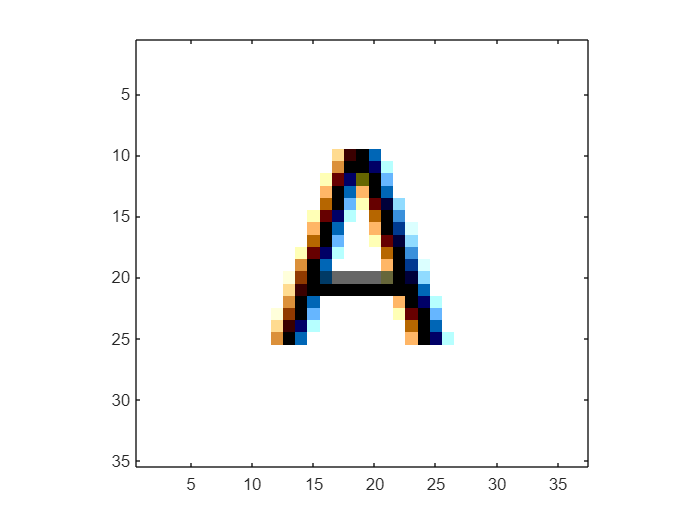

% read the image as a matrix of positions and display the image

A=imread('C:\Users\nguyh\OneDrive\Desktop\ASU\Fall 2023\A.png');    %load the picture
image(A), axis image                                                %display the image

A

A = 35×37×3 uint8 array
A(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255

% Initialize corresponding matrix for electric field values

s = size(A);
E = zeros(s(1,1),s(1,2));                               %Field matrix equal to size of picture

% define given quantities

L = 1;                                                  %Distance from paper in m
m = 1;                                                  %mass in kg
w = 1;                                                  %width of cathode in m
p = 1;                                                  %pixel length in m
u = 1;                                                  %initial velocity in m/s
q = 1;                                                  %Charge of the ink
dp = 1;                                                 %Distance of the electric plates

% --Electric Field Matrix--
% For each row in each column of the positions matrix, if there is a black dot,
% store the corresponsing electric field value with the center
% at index 0
% j*p is used as distance d in order to account for pixel length

for i=1:s(1,1)
    for j=1:s(1,2)
        if (A(i,j) < 127.5)                             %Checks if element is dark (with a threshold of 127.5)
            E(i,j) = (m*u^2*j*p) / ((L - w/2)*q*w);     %Calculates corresponding electric field value needed to output distance
        end
    end
end

% --DC Voltage Waveform--
% The volatge waveform takes the electric field waveform and outputs a
% singe row vector in which 0 indicates a new line, and multiplies electric
% field elements by distance dp in order to obtain the corresponding voltage

S = sum(E,2);                                           %Shortcut to check if a row is blank
t = 1;                                                  %Keeps track of voltage waveform array size
V = zeros(1,1);                                         %Initializes voltage waveform
for i=1:s(1,1)                                          %Iterates through every row of the Electric Field Matrix
    if (S(i,1) ~= 0)                                    %Checks if row is blank
        for j=1:s(1,2)                                  
            if (E(i,j) ~= 0)                            %If not, takes any non-zero values in that row
                V(1,t) = E(i,j)*dp;                     %and multiplies it by the distance to get voltage
                t = t+1;                                %Increases value of t by one to let us know the increase in size
            end                                         
        end
    end
    V(1,t) = 0;                                         %The 0 lets us know its going to the next line
    t = t+1;
end

% --Image output--
% Converting the voltage waveform into an output onto a 2-D coordinate
% system, the output is two rows: the first is the x values and the second
% is the y values. 
% The code iterates from the top down, if the value of the initial DC waveform vector is a 0, the y axis is
% decremented by 1

VoltageSize = size(V);
VoltageSize = VoltageSize(1,2);                                %Gives us amount of columns in the voltage waveform                      
Output = zeros(2,VoltageSize);                                 %Output contains two rows, first row the x position and second row y position.
y = s(1,1);                                                    %Will contain a coordinate value for every value in Voltage Waveform
for i=1:VoltageSize                                            %Iterates through array
    if (V(1,i) == 0)                                           %If Voltage value is zero, that signifies the next line
        Output(1,i) = 0;                                       %Sets X and Y to zero
        Output(2,i) = 0;
        y = y-1;                                               %Decrease the value of y to go to next line
    else
        Output(1,i) = (V(1,i)/dp)*q*w*(L-w/2) / (u^2*m*p);     %If not 0, solves for x value using the deflection equation
        Output(2,i) = y;                                       %Sets y value to line number
    end
end
Output

Output =      0     0     0     0     0     0     0     0     0    18    19    20     0    18    19    20     0    17    18    19    20    21     0    17    18    20    21     0    17    18    20    21     0    16    17    21    22     0    16    17    21    22     0    16    17    21    22     0    15    16
     0     0     0     0     0     0     0     0     0    26    26    26     0    25    25    25     0    24    24    24    24    24     0    23    23    23    23     0    22    22    22    22     0    21    21    21    21     0    20    20    20    20     0    19    19    19    19     0    18    18


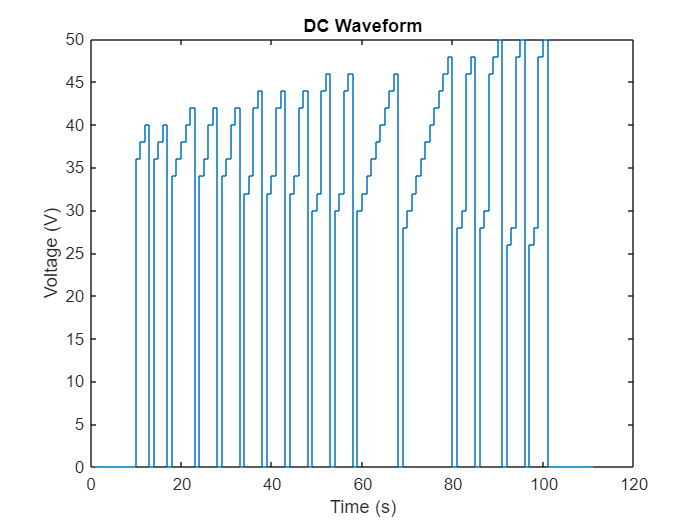

% --DC Waveform, static output--
% Outputs Voltage vs Time plot for the DC Waveform as a stair plot
x = 1:1:VoltageSize;
stairs(x,V)
title('DC Waveform')
xlabel('Time (s)');
ylabel('Voltage (V)');

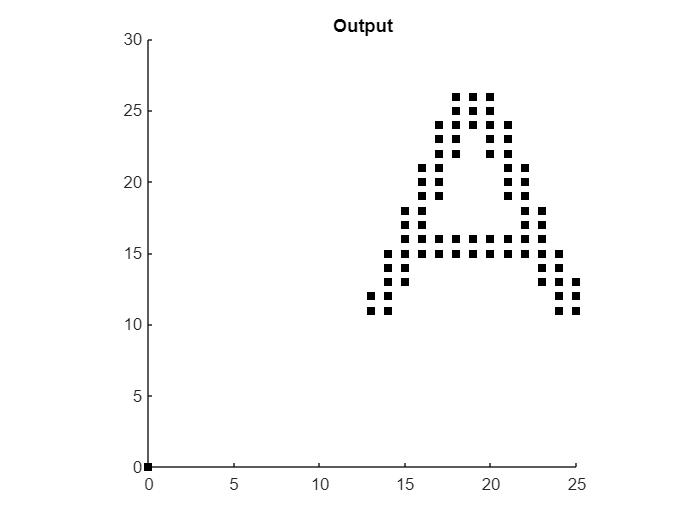


% --Image Output, static output--
% Outputs the corresponding image to the DC waveform above on a 2-D
% coordinate system as a scatter plot
X = Output(1,:);
Y = Output(2,:);
scatter(X,Y, 36, 'k', 'square', 'filled')
axis square;
title('Output');

% --gif output--
% Creates two tiles, one for the DC waveform and one for the image output.
% For each voltage waveform value, a point is placed and animated in each
% tile. The DC waveform is a stair plot, the image output is a scatter
% plot. The gif is saves as 'DCWaveform.gif'
tiledlayout(2,1)
for n = 1:VoltageSize
   nexttile(1)
   stairs(x(1:n),V(1:n));
   title('DC Waveform')
   xlabel('Time (s)');
   ylabel('Voltage (V)');

   nexttile(2)
   scatter(X(1:n),Y(1:n), 36, 'k', 'square', 'filled');
   axis square;
   title('Output');
   exportgraphics(gcf,'DCWaveform (G).gif','Append',true);
end